% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 3; %the ratio amax/xmax

xmax = 1;
N = 21; % total number of bins on [-xmax,+xmax]
x_bin_size = 2*xmax/N;
% q=N/2;% quantization level
x_grid = linspace(-xmax+0.5*x_bin_size,xmax-0.5*x_bin_size, N)

x_grid =    -0.9524   -0.8571   -0.7619   -0.6667   -0.5714   -0.4762   -0.3810   -0.2857   -0.1905   -0.0952         0    0.0952    0.1905    0.2857    0.3810    0.4762    0.5714    0.6667    0.7619    0.8571    0.9524


M = N;

% We assign a distribution to X\in x_grid

x_P = ones(1,M)/M; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

% figure
% plot(x_grid,x_P,'o',LineWidth=1.5);
% xlabel("x",FontSize=13);
% ylabel("P(x)",FontSize=13);
% grid on

% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = exp(linspace(0,log(8),20));

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
VarOptWorst = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [varVector,pMatrix,a_grid] =... 
        opt_variance(eps_grid(i),delta,r,axRatio,x_grid,x_P);
    VarOpt(i) = x_P*varVector;
    VarOptWorst(i) = max(varVector);
end

--------------------------------
eps = 1.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0197    0.5432    0.2001    0.1320    0.0316   -0.1110   -0.1282   -0.0505    0.0867    0.0667         0   -0.0868    0.1142   -0.6407   -0.1449    0.1110   -0.1493   -0.1711    0.4714   -0.0095   -0.1856


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.6319    1.9519    2.1323    2.1620    2.1323    2.0827    2.0035    1.9380    1.8957    1.8428    1.7996    1.8428    1.8957    1.9380    2.0035    2.0827    2.1323    2.1620    2.1323    1.9519    1.6319


--------------------------------
eps = 1.115658, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.1455   -0.1987   -0.1702   -0.0230   -0.2001   -0.0555    0.0178   -0.1443    0.3334   -0.0635         0    0.2021   -0.2629   -0.0904   -0.0483    0.1110   -0.0269    0.1626    0.0408    0.1126    0.1525


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.4448    1.7582    1.8674    1.8757    1.8466    1.7894    1.7168    1.6536    1.6106    1.5573    1.5274    1.5573    1.6106    1.6536    1.7168    1.7894    1.8466    1.8757    1.8674    1.7582    1.4448


--------------------------------
eps = 1.244693, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0526    0.0937    0.0980   -0.1314   -0.0647    0.1665    0.0973   -0.0438   -0.0509   -0.0779         0   -0.0187    0.0649    0.0416   -0.2734   -0.4441   -0.2513   -0.2016   -0.0423    0.1096    0.0805


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.3166    1.5673    1.6333    1.6312    1.5942    1.5317    1.4600    1.3743    1.3219    1.3072    1.3165    1.3072    1.3219    1.3743    1.4600    1.5317    1.5942    1.6312    1.6333    1.5673    1.3166


--------------------------------
eps = 1.388651, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

    0.0114    0.0109    0.0005   -0.0132    0.0038         0   -0.0111   -0.0035    0.0093   -0.0022   -0.0056    0.0100    0.0161    0.0110    0.0004    0.1887   -0.0143    0.0140   -0.0112    0.0045    0.0775


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.1830    1.3588    1.4050    1.3977    1.3560    1.2966    1.2229    1.1377    1.1088    1.1185    1.1187    1.1185    1.1088    1.1377    1.2229    1.2966    1.3560    1.3977    1.4050    1.3588    1.1830


--------------------------------
eps = 1.549260, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0065   -0.0275   -0.0254   -0.0634    0.0045    0.0555    0.0827    0.1039   -0.1780   -0.0208    0.1665   -0.0780    0.0619    0.0960   -0.0844         0   -0.1144    0.0325   -0.0321   -0.0114    0.1959


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.0692    1.1807    1.2065    1.1828    1.1299    1.0617    0.9860    0.9344    0.9094    0.9189    0.9190    0.9189    0.9094    0.9344    0.9860    1.0617    1.1299    1.1828    1.2065    1.1807    1.0692


--------------------------------
eps = 1.728444, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0427   -0.0064    0.0010   -0.2090   -0.0844    0.0194    0.0032   -0.0001   -0.0029    0.0054         0    0.0113   -0.0215   -0.0058   -0.0038    0.0056   -0.0048   -0.0137   -0.0027    0.0037   -0.0143


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.9500    1.0132    1.0122    0.9746    0.9194    0.8466    0.7980    0.7676    0.7387    0.7180    0.7181    0.7180    0.7387    0.7676    0.7980    0.8466    0.9194    0.9746    1.0122    1.0132    0.9500


--------------------------------
eps = 1.928352, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0226   -0.0506   -0.0777    0.7839    0.4651    0.0833    0.0807   -0.0843   -0.0100    0.0447   -0.0555   -0.0358    0.2187    0.1293   -0.0117   -0.0278   -0.0230   -0.2496   -0.3171    0.0549   -0.1565


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8202    0.8377    0.8174    0.7740    0.7131    0.6744    0.6498    0.6253    0.5937    0.5639    0.5456    0.5639    0.5937    0.6253    0.6498    0.6744    0.7131    0.7740    0.8174    0.8377    0.8202


--------------------------------
eps = 2.151381, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0921   -0.0204   -0.1694    0.1044    0.0097    0.0833   -0.0752    0.0976   -0.0256    0.0904   -0.0278   -0.2368    0.0700    0.1219    0.0486    0.0555    0.1924    0.0471    0.0283    0.0576   -0.0048


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.6878    0.6761    0.6439    0.5955    0.5565    0.5420    0.5165    0.4901    0.4638    0.4308    0.4000    0.4308    0.4638    0.4901    0.5165    0.5420    0.5565    0.5955    0.6439    0.6761    0.6878


--------------------------------
eps = 2.400205, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.1632   -0.0633    0.0035   -0.1280   -0.0020   -0.0555    0.0279    0.0675   -0.0957    0.0375    0.0278   -0.0333   -0.0130    0.0827    0.0970   -0.0416   -0.0311   -0.1269   -0.1289    0.0371   -0.0473


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.5796    0.5410    0.4958    0.4581    0.4364    0.4140    0.3910    0.3734    0.3464    0.3193    0.3125    0.3193    0.3464    0.3734    0.3910    0.4140    0.4364    0.4581    0.4958    0.5410    0.5796


--------------------------------
eps = 2.677808, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.2336   -0.0004    0.0070   -0.0162   -0.0388    0.0056    0.0005    0.0052   -0.0035    0.0173   -0.0028   -0.0048    0.0002    0.0017    0.0055    0.0028   -0.0061   -0.0099   -0.0217   -0.0033    0.0144


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.4711    0.4203    0.3678    0.3546    0.3390    0.3221    0.2967    0.2699    0.2429    0.2248    0.2231    0.2248    0.2429    0.2699    0.2967    0.3221    0.3390    0.3546    0.3678    0.4203    0.4711


--------------------------------
eps = 2.987518, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0643    0.0059    0.0852   -0.0307   -0.0459    0.0139    0.0096    0.0158    0.0227   -0.0186    0.1665    0.0112   -0.0293    0.2259    0.1041    0.0833   -0.3669    0.1083   -0.5362   -0.0606   -0.0598


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.3497    0.2937    0.2793    0.2721    0.2599    0.2422    0.2237    0.1966    0.1710    0.1676    0.1669    0.1676    0.1710    0.1966    0.2237    0.2422    0.2599    0.2721    0.2793    0.2937    0.3497


--------------------------------
eps = 3.333048, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.2049   -0.0182   -0.0033    0.0114   -0.0048   -0.0042   -0.0015    0.0197   -0.0616   -0.0011   -0.0056   -0.0020    0.0284    0.0244    0.0007   -0.0031    0.0005    0.0013    0.0032    0.0055   -0.0040


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.2577    0.2258    0.2147    0.2023    0.1891    0.1751    0.1508    0.1248    0.1248    0.1248    0.1248    0.1248    0.1248    0.1248    0.1508    0.1751    0.1891    0.2023    0.2147    0.2258    0.2577


--------------------------------
eps = 3.718541, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.2480    0.2052    0.4890   -0.6157    0.1210    0.7980    0.1068    0.0588    0.1056   -0.1894         0    0.1062    0.0838    0.0214   -0.5410    0.1041   -0.0119    0.2082   -0.0988    0.0953   -0.0143


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1834    0.1677    0.1606    0.1516    0.1344    0.1162    0.0981    0.0924    0.0875    0.0818    0.0799    0.0818    0.0875    0.0924    0.0981    0.1162    0.1344    0.1516    0.1606    0.1677    0.1834


--------------------------------
eps = 4.148620, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0195   -0.0031    0.1256   -0.0232    0.0023   -0.0035   -0.0051    0.0023   -0.0007    0.0231    0.0139   -0.0216   -0.0151   -0.0099    0.0255   -0.0208   -0.0239   -0.0336   -0.0243   -0.0039    0.0477


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1290    0.1200    0.1114    0.1023    0.0932    0.0826    0.0695    0.0624    0.0572    0.0572    0.0572    0.0572    0.0572    0.0624    0.0695    0.0826    0.0932    0.1023    0.1114    0.1200    0.1290


--------------------------------
eps = 4.628441, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.0625    0.0120   -0.1193    0.1046   -0.0953   -0.0867    0.0773    0.0195   -0.6409   -0.0401   -0.0694   -0.1342   -0.0440    0.0058    0.0774    0.0347   -0.6030   -0.0480    0.0173   -0.0155   -0.0016


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0910    0.0820    0.0802    0.0771    0.0628    0.0537    0.0510    0.0429    0.0338    0.0313    0.0330    0.0313    0.0338    0.0429    0.0510    0.0537    0.0628    0.0771    0.0802    0.0820    0.0910


--------------------------------
eps = 5.163757, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0147    0.0075   -0.0148   -0.2712   -0.0689    0.0069   -0.0090   -0.0157    0.0005   -0.0055         0   -0.0016   -0.0027   -0.0039   -0.0019    0.0113    0.0198   -0.0156   -0.0338   -0.0199   -0.0036


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0623    0.0617    0.0535    0.0444    0.0353    0.0347    0.0298    0.0264    0.0248    0.0227    0.0218    0.0227    0.0248    0.0264    0.0298    0.0347    0.0353    0.0444    0.0535    0.0617    0.0623


--------------------------------
eps = 5.760986, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

    0.0004    0.0016    0.0009   -0.0006    0.0005         0    0.0000   -0.0011   -0.0006   -0.0000   -0.0021   -0.0005    0.0016    0.0000   -0.0002   -0.0005   -0.0007    0.0005    0.0006   -0.0001    0.1613


Distribution validity check (should be all ones):


ans = 1×21
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×21
    0.0350    0.0350    0.0350    0.0273    0.0255    0.0233    0.0195    0.0173    0.0163    0.0157    0.0157    0.0157    0.0163    0.0173    0.0195    0.0233    0.0255    0.0273    0.0350    0.0350    0.0350


--------------------------------
eps = 6.427290, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×21
1.0e-16 *

   -0.0573    0.1687   -0.0136   -0.5325   -0.0199    0.0152   -0.0353    0.0473   -0.0130    0.1196    0.3469    0.0387    0.2321    0.0430   -0.1339   -0.0369   -0.0270    0.0238    0.1208   -0.3310   -0.5876


Distribution validity check (should be all ones):


ans = 1×21
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×21
    0.0215    0.0215    0.0210    0.0165    0.0150    0.0138    0.0128    0.0120    0.0115    0.0112    0.0112    0.0112    0.0115    0.0120    0.0128    0.0138    0.0150    0.0165    0.0210    0.0215    0.0215


--------------------------------
eps = 7.170657, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×21
1.0e-16 *

   -0.1001    0.0048   -0.0567    0.1035    0.1480   -0.0390    0.0091    0.0016    0.0052   -0.1243    0.2602    0.5161    0.3466    0.0651   -0.1319    0.6053   -0.5106    0.2052   -0.3458    0.3460   -0.2141


Distribution validity check (should be all ones):


ans = 1×21
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×21
    0.0142    0.0169    0.0155    0.0134    0.0134    0.0098    0.0051    0.0043    0.0037    0.0033    0.0031    0.0033    0.0037    0.0043    0.0051    0.0098    0.0134    0.0134    0.0155    0.0169    0.0142


--------------------------------
eps = 8.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×21
1.0e-16 *

    0.0038   -0.0016   -0.0022   -0.0050   -0.0077   -0.0005   -0.0055    0.0023   -0.3615   -0.2189    0.0932    0.1781    0.2756    0.1190   -0.9259    0.3915   -0.3090    0.3111   -0.0448    0.1564   -0.0068


Distribution validity check (should be all ones):


ans = 1×21
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×21
    0.0090    0.0078    0.0067    0.0057    0.0048    0.0041    0.0035    0.0030    0.0026    0.0024    0.0023    0.0024    0.0026    0.0030    0.0035    0.0041    0.0048    0.0057    0.0067    0.0078    0.0090


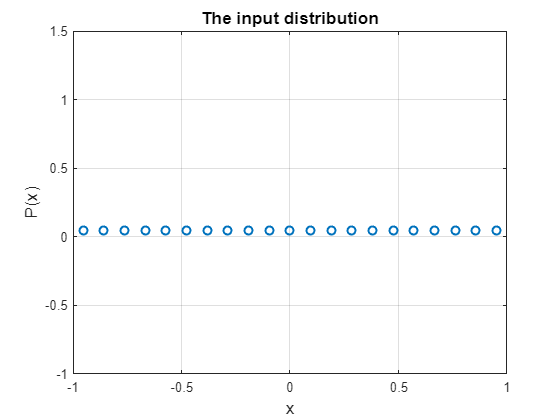

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end

% The variance vector of Duchi mechanism
VarDuchi = zeros(1,length(eps_grid));
VarDuchiWorst = zeros(1,length(eps_grid));
var_duchi = @(ti,eps) ((exp(eps)+1)/(exp(eps)-1)).^2 - ti.^2;
for i = 1:length(eps_grid)
    temp = var_duchi(x_grid,eps_grid(i));
    VarDuchi(i) = temp *x_P';
    VarDuchiWorst(i) = max(temp);
end

% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
VarPiecewiseWorst = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    temp = var_piecewise(x_grid,eps_grid(i));
    VarPiecewise(i) = temp *x_P';
    VarPiecewiseWorst(i) = max(temp);
end

% The variance vector of Hybrid mechanism
VarHybrid = zeros(1,length(eps_grid));
VarHybridWorst = zeros(1,length(eps_grid));
alpha = @(eps) sign(max(eps-0.61,0))*(1-exp(-eps/2));
var_hybrid = @(ti,eps) alpha(eps)*var_piecewise(ti,eps) + (1-alpha(eps))*var_duchi(ti,eps);
for i = 1:length(eps_grid)
    temp = var_hybrid(x_grid,eps_grid(i));
    VarHybrid(i) = temp *x_P';
    VarHybridWorst(i) = max(temp);
end

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",FontSize=13);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

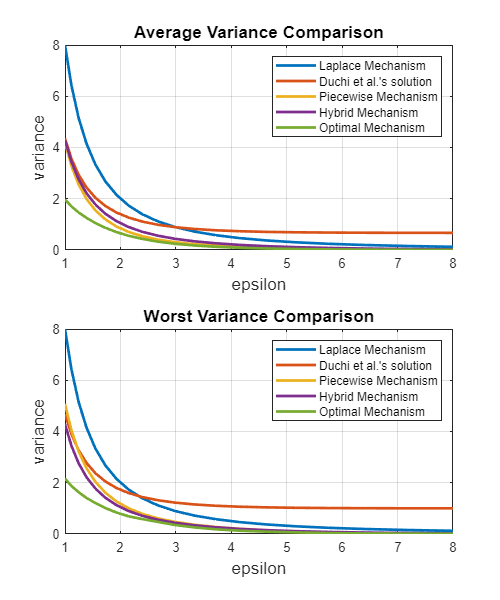


figure;
f = figure;
f.Position = [0 0 500 600];

subplot(2,1,1)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchi,LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,LineWidth=2);
hold on
plot(eps_grid,VarHybrid,LineWidth=2);
hold on
plot(eps_grid,VarOpt,LineWidth=2);

title("Average Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

subplot(2,1,2)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchiWorst,LineWidth=2);
hold on
plot(eps_grid,VarPiecewiseWorst,LineWidth=2);
hold on
plot(eps_grid,VarHybridWorst,LineWidth=2);
hold on
plot(eps_grid,VarOptWorst,LineWidth=2);
title("Worst Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

q = 10; % quantization level
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 4; %the ratio amax/xmax
eps = 2; % the privacy parameter

xmax = 1;
xmax = floor(xmax*q)/q; % We need to make sure they are integers
M = 2*xmax*q+1; % total amount of x samples
x_grid = linspace(-xmax,xmax,M);

% We assign a distribution to X\in x_grid

x_P = ones(1,M)/M; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

[varVector,pMatrix,a_grid] =...
    opt_variance(eps,delta,r,axRatio,x_grid,x_P);

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0441   -0.0290    0.0057    0.0073   -0.0051   -0.1915    0.0008   -0.0007   -0.1023    0.0031   -0.0278   -0.0051    0.0073    0.0014   -0.0122    0.0736    0.0003    0.0026    0.0016    0.0268   -0.0077


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.0336    0.8948    0.8684    0.8367    0.8026    0.7674    0.7382    0.7061    0.6662    0.6263    0.5983    0.6263    0.6662    0.7061    0.7382    0.7674    0.8026    0.8367    0.8684    0.8948    1.0336


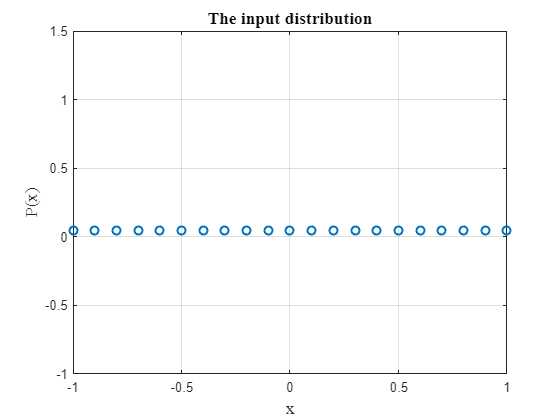

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",'FontSize',13,'FontName','Times');
xlabel("x",'FontSize',13,'FontName','Times');
ylabel("P(x)",'FontSize',13,'FontName','Times');
grid on

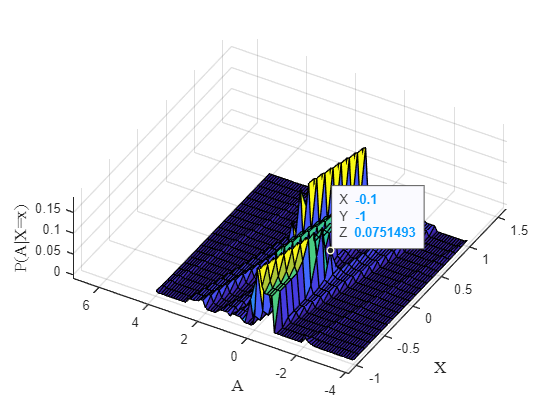


figure
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
surf(X_grid,Y_grid,pMatrix');
xlabel("X",'FontSize',13,'FontName','Times');
ylabel("A",'FontSize',13,'FontName','Times');
zlabel("P(A|X=x)",'FontSize',13,'FontName','Times');